# Visualizations with Vector Data

You've already seen line plots, bar graphs, pie charts, and histograms created in MATLAB. In this reading, you'll see more of these as well as area, scatter, stem, and stair plots. 

This Live Script generates visualizations of the operating costs and revenue generated throughout the day on Monday and Saturday at the pizza shop ("revenue generated" is, here, just how much money the shop brought in by selling pizzas). Using various kinds of visualizations reveals many different facts about the data, including many interesting trends and patterns in the data.

## Loading the Data

### Pizza Data

Use the `load` command to load `pizzaData.mat`.

load test.mat

### Operating Costs

The hourly operating costs on Monday and Saturday were calculated by taking into account the work schedules and pay rates of each pizza shop employee, utilities costs, rent costs, and the cost of ingredients used per hour. The two 24 element vectors defined below, `operatingCostMonday` and `operatingCostSaturday`, contain the operating costs (in dollars) from every hour of the day on Monday and Saturday.

% Define 24 element vector for Monday (dollars per hour)
operatingCostMonday     = [8; 8; 8; 8; 8; 8; 8; 8; 8; 85; 100; 111; 166; 160; 162; 159; 183; 167; 150; 117; 30; 8; 8; 8]

operatingCostMonday =      8
     8
     8
     8
     8
     8
     8
     8
     8
    85



% Define 24 element vector for Saturday (dollars per hour)
operatingCostSaturday   = [8; 8; 8; 8; 8; 8; 8; 8; 8; 108; 141; 254; 334; 263; 302; 373; 395; 344; 344; 272; 112; 8; 8; 8]

operatingCostSaturday =      8
     8
     8
     8
     8
     8
     8
     8
     8
   108


## **Visualizing Operating Costs**

### `Plot`

The first line below creates a line plot with the values of `operatingCostMonday` on the y-axis and the index of `operatingCostMonday` on the x-axis. The index starts at 1 and, since there are 24 elements in `operatingCostMonday`, goes to 24.

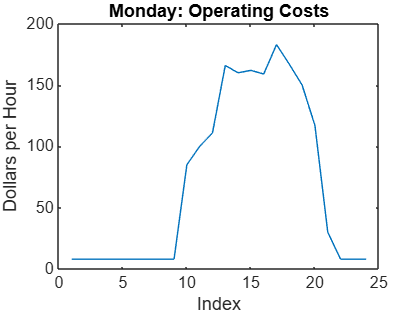

plot(operatingCostMonday)
title('Monday: Operating Costs')
ylabel('Dollars per Hour')
xlabel('Index')

It is useful to see the operating costs from Monday and Saturday on the same figure. Accomplish this by using `hold on`. Don't forget to use `hold off` after using `hold on`.

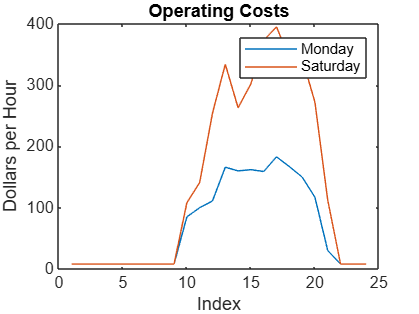

plot(operatingCostMonday)
hold on
plot(operatingCostSaturday)
hold off
legend('Monday','Saturday')
title('Operating Costs')
xlabel('Index')
ylabel('Dollars per Hour')

### `Histogram`

The operating costs from Monday and Saturday were just compared by using the `plot` function. There are many more visualization functions that help analyze data further. For example, with `histogram`, you can visualize the distribution of the operating costs. Use `histogram` to visualize the distribution of operating costs on Monday.

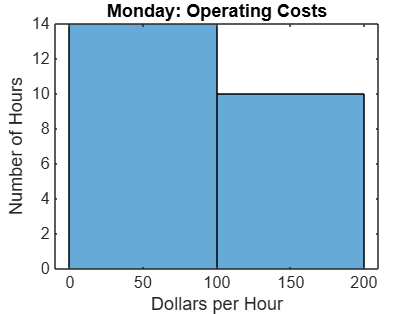

histogram(operatingCostMonday)
title('Monday: Operating Costs')
xlabel('Dollars per Hour')
ylabel('Number of Hours')

As with `plot`, two histograms can be placed on the same figure. Use `histogram` to visualize the operating costs from Monday and Saturday on the same figure.

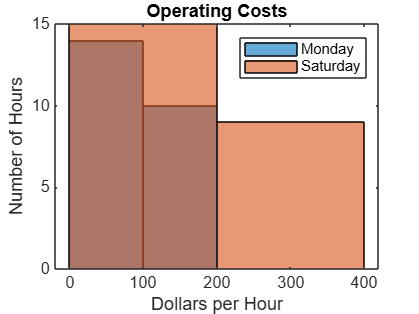

histogram(operatingCostMonday)
hold on
histogram(operatingCostSaturday)
hold off
legend('Monday','Saturday')
title('Operating Costs')
xlabel('Dollars per Hour')
ylabel('Number of Hours')

MATLAB makes the histogram on top transparent by default. This allows you to see both histograms.

We recommend that you experiment with the bin size to find new, useful configurations. Splitting the data into similarly sized bins, for example, helps to compare both distributions. To do this, specify the *edges *of the bins and include this information when using the `histogram` function.

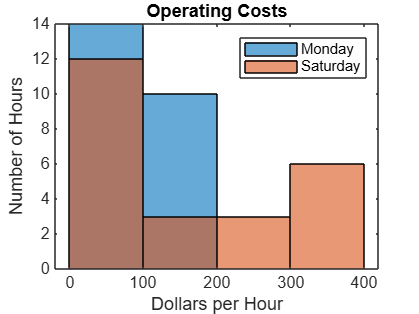

binEdges = [0 100 200 300 400];

histogram(operatingCostMonday,binEdges)
hold on
histogram(operatingCostSaturday,binEdges)
hold off
legend('Monday','Saturday')
title('Operating Costs')
xlabel('Dollars per Hour')
ylabel('Number of Hours')

On Monday, the operating cost was never more than $200 per hour. But on Saturday, there were three hours with operating costs between $200 per hour and $300 per hour and six hours with operating costs between $300 per hour and $400 per hour.

How would you make it so these histograms each have 8 bins that are 50 units wide rather than 4 bins that are 100 units wide? Copy the code from above, paste it below, and change it to produce histograms with 8 bins that are 50 units wide.

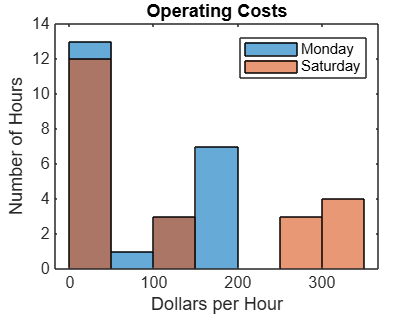

binEdges = [0:50:350];

histogram(operatingCostMonday,binEdges)
hold on
histogram(operatingCostSaturday,binEdges)
hold off
legend('Monday','Saturday')
title('Operating Costs')
xlabel('Dollars per Hour')
ylabel('Number of Hours')

## **Visualizing Operating Costs and Revenue**

To understand how profitable the shop was throughout each of these days, the revenue generated every hour needs to be calculated. For this Live Script, the revenue generated is assumed to be equivalent to the money brought in by selling pizzas.

Thus, begin by selecting the relevant data from the `pizzasCompleted` vector.

% Select the data from Monday
pizzasCompletedMonday = pizzasCompleted(1:25)

pizzasCompletedMonday =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Select the data from Saturday
pizzasCompletedSaturday = pizzasCompleted(120:144)

pizzasCompletedSaturday =         1707
        1707
        1707
        1707
        1707
        1707
        1707
        1707
        1707
        1707


Both of these vectors (`pizzasCompletedMonday` and `pizzasCompletedSaturday`) contain 25 elements. Applying the `diff` function to these vectors results in two 24 element vectors because `diff` calculates the difference between each element in the vector.

% Calculate the pizzas sold every hour on Monday
pizzasPerHourMonday     = diff(pizzasCompletedMonday)

pizzasPerHourMonday =      0
     0
     0
     0
     0
     0
     0
     0
     0
     9



% Calculate the pizzas sold every hour on Saturday
pizzasPerHourSaturday   = diff(pizzasCompletedSaturday)

pizzasPerHourSaturday =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Now you have two 24 element vectors that contain the pizzas sold every hour on Monday and Saturday. Since the average price of a pizza is $15, you can estimate the hourly revenue (in dollars) by multiplying by 15.

% Calculate the money made every hour on Monday
revenueMonday   = 15*pizzasPerHourMonday;

% Calculate the money made every hour on Saturday
revenueSaturday = 15*pizzasPerHourSaturday

revenueSaturday =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


These vectors (`revenueMonday` and `revenueSaturday`) are a good estimate of how much revenue was generated throughout the day (that is, of how much money was brought in by selling pizzas) on Monday and Saturday at the pizza shop. Both of these vectors are 24 elements long.

### `Area`

Compare the operating cost and revenue generated throughout the day on Monday by using the `area` function, which creates an area plot. 

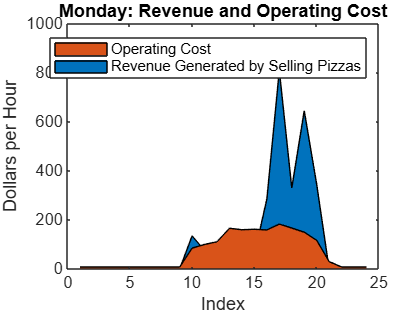

area(revenueMonday)
hold on
area(operatingCostMonday)
hold off
legend('Revenue Generated by Selling Pizzas', 'Operating Cost')
title('Monday: Revenue and Operating Cost')
xlabel('Index')
ylabel('Dollars per Hour')

The area plot clearly shows the hours when the revenue generated was larger than the operating cost. It also provides a clear visualization of how the total revenue on Monday compares to the total operating cost on Monday, since these totals are what is represented by the area of the blue and orange shaded areas, respectively.

Next, use the `area` function again to compare the operating cost and revenue generated throughout the day on Saturday.

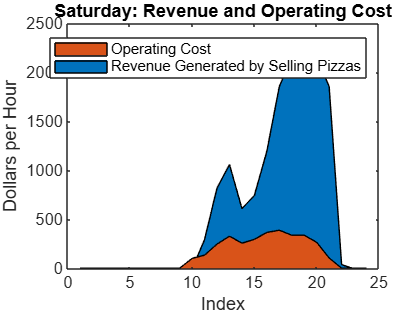

area(revenueSaturday)
hold on
area(operatingCostSaturday)
hold off
legend('Revenue Generated by Selling Pizzas', 'Operating Cost')
title('Saturday: Revenue and Operating Cost')
xlabel('Index')
ylabel('Dollars per Hour')

It looks like the revenue generated per hour on Saturday was, in general, much higher than the hourly operating costs. Also, since the blue shaded area is much larger than the orange shaded area, the total revenue on Saturday was much higher than the total operating cost on Saturday.

### `Scatter`

The `scatter` function allows you to plot individual data points. This helps to make the relationship between revenue and operating cost understandable.

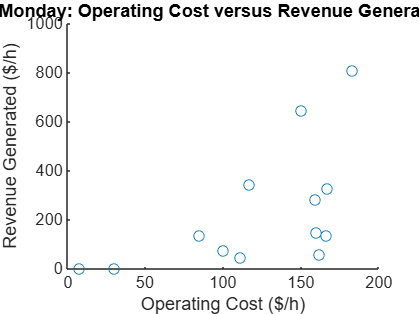

scatter(operatingCostMonday, revenueMonday)
title('Monday: Operating Cost versus Revenue Generated')
xlabel('Operating Cost ($/h)')
ylabel('Revenue Generated ($/h)')

It is useful to plot the line *y = x* (which is, in this case, the line Operating Cost = Revenue Generated) on this figure. Plot this line by using the `plot` function with the vector `[0 200]` for both the x-values and y-values.

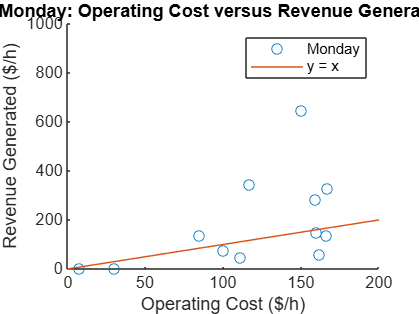

xValues = [0 200];
yValues = [0 200];

scatter(operatingCostMonday, revenueMonday)
hold on
plot(xValues,yValues)
hold off
legend('Monday','y = x')
title('Monday: Operating Cost versus Revenue Generated')
xlabel('Operating Cost ($/h)')
ylabel('Revenue Generated ($/h)')

Any points *above *the line *y = x* represent hours when the revenue generated was *higher than *the operating cost. In other words, points above the line represent profitable hours. Any points *below *this line represent hours when the revenue generated was *lower than *the operating cost, meaning that the pizza shop lost money during those hours.

Finally, create a figure that has two scatter plots for Monday and Saturday, as well as the line *y = x. *This time, when creating the line *y = x*, use the vector `[0 400]` for both the x-values and y-values, since the data from Saturday spans over a larger range of values.

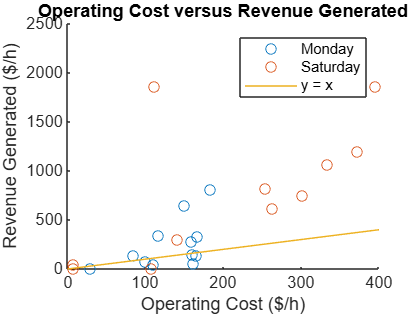

xValues = [0 400];
yValues = [0 400];

scatter(operatingCostMonday, revenueMonday)
hold on
scatter(operatingCostSaturday, revenueSaturday)
plot(xValues, yValues)
hold off
legend('Monday','Saturday','y = x')
title('Operating Cost versus Revenue Generated')
xlabel('Operating Cost ($/h)')
ylabel('Revenue Generated ($/h)')

Notice all the points from Saturday that are above the line. It looks like Saturday was much more profitable than Monday!

## **Visualizing Profit**

In this final section, you'll compare how profitable the shop was on Monday with how profitable the shop was on Saturday. 

First, calculate the profit for each hour throughout the day by subtracting operating costs from revenue generated.

% Calculate the profit for every hour on Monday (in dollars)
profitMonday    = revenueMonday  -  operatingCostMonday

profitMonday =     -8
    -8
    -8
    -8
    -8
    -8
    -8
    -8
    -8
    50



% Calculate the profit for every hour on Saturday (in dollars)
profitSaturday  = revenueSaturday  -  operatingCostSaturday

profitSaturday =     -8
    -8
    -8
    -8
    -8
    -8
    -8
    -8
    -8
  -108


### `Stem`

Now, create a stem plot to visualize the profitability of each hour on Monday.

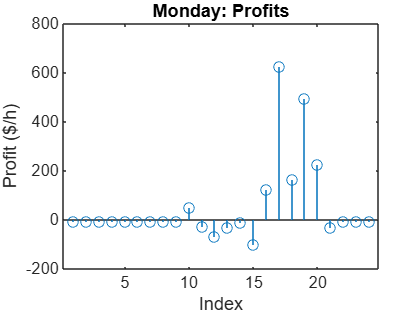

stem(profitMonday)
title('Monday: Profits')
ylabel('Profit ($/h)')
xlabel('Index')

And make a similar plot on a separate figure to visualize the profitability of each hour on Saturday.

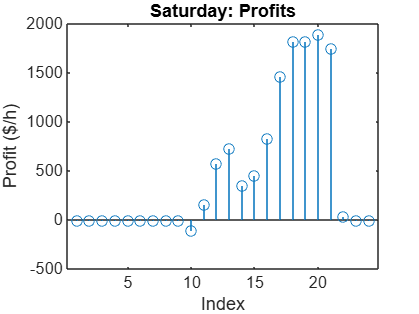

stem(profitSaturday)
title('Saturday: Profits')
ylabel('Profit ($/h)')
xlabel('Index')

You could have placed these two stem plots on the same figure, but graphing them separetely allows you to study each trend separately, without getting overwhelmed by information. Comparing these two stem plots, you can see that Saturday was much more profitable.

### `Stairs`

You could have used stair plots instead of stem plots to represent this data. Copy the code that created each of the stem plots above and replace `stem` with `stairs` to see the same data represented by stair plots.

Use `stairs` to represent the profit throughout the day on Monday.

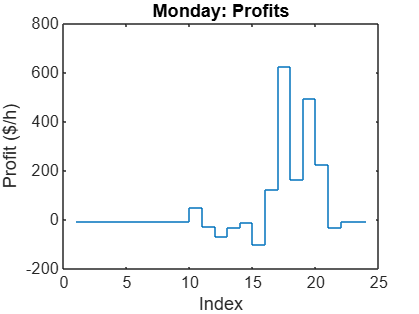

stairs(profitMonday)
title('Monday: Profits')
ylabel('Profit ($/h)')
xlabel('Index')

Use `stairs` to represent the profit throughout the day on Saturday.

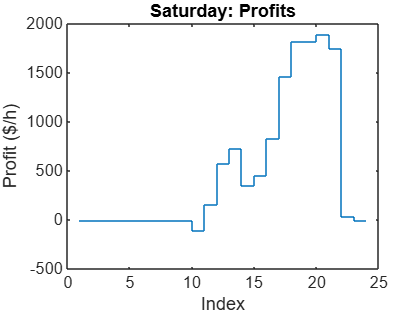

stairs(profitSaturday)
title('Saturday: Profits')
ylabel('Profit ($/h)')
xlabel('Index')

## **Suggestions for Further Exploration with Visualizations**

In this reading, you encountered the functions `plot`, `histogram`, `scatter`, `area`, `stem`, and` stairs`. You should take the time to make some more visualizations using these functions. 

For example, represent the profitability on Monday and Saturday using `histogram`. Create a figure below with the profits from Monday represented by a histogram and the profits from Saturday represented by another histogram on the same figure. If you need help getting started, copy the histogram code from before, paste it below, and change it to graph the profits from Monday and Saturday.

Set the bins on these histograms to `[-200 0 200 400 600 800 1000 1200 1400 1600 1800 2000]` before you explore with other bin edges. 

**Tip:** Use the [colon](https://www.mathworks.com/help/matlab/ref/colon.html) operator to quickly create the vector of bin edges: `binEdges = -200:200:2000`

If you didn't already, go back and use `legend`, `title`, `xlabel`, and `ylabel` to annotate your figure.

Feel free to explore and make your own visualizations.

See the [documentation](https://www.mathworks.com/help/matlab/2-and-3d-plots.html) for more details on the plot types included here, and many others[.](https://www.mathworks.com/help/matlab/2-and-3d-plots.html.)

*Copyright 2021 The MathWorks, Inc.*